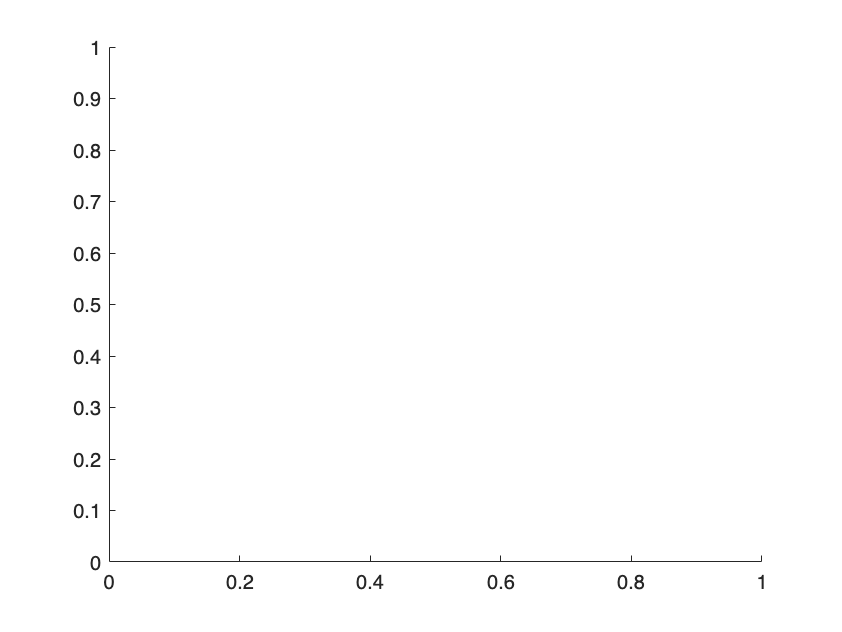

cla;

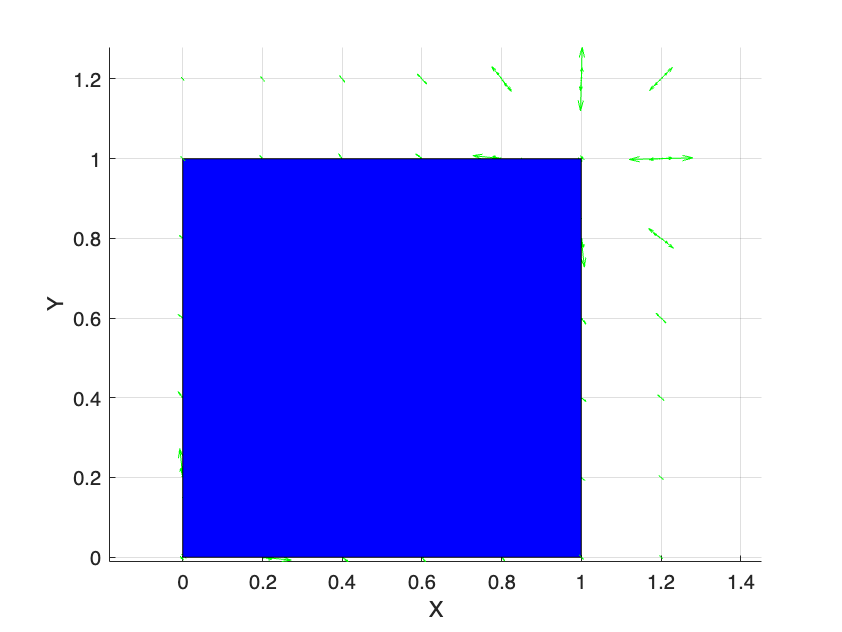

clear all;
vertices = [
    1, 1, 0;
    1, 0, 0;
    0, 0, 0;
    0, 1, 0;
    1, 1, 0.2;
    1, 0, 0.2;
    0, 0, 0.2;
    0, 1, 0.2;
    
    1, 1, 1;
    1, 0, 1;
    0, 0, 1;
    0, 1, 1;
    1, 1, 1.2;
    1, 0, 1.2;
    0, 0, 1.2;
    0, 1, 1.2;
];

caras = [
    1, 2, 3, 4;
    5, 6, 7, 8;
    1, 5, 6, 2;
    2, 6, 7, 3;
    3, 7, 8, 4;
    4, 8, 5, 1;

    9, 10, 11, 12;
    13, 14, 15, 16;
    9, 13, 14, 10;
    10, 14, 15, 11;
    11, 15, 16, 12;
    12, 16, 13, 9;
];

% Definir colores distintos para cada cara
colores = [
    1, 0, 0;  % Rojo
    1, 0, 0;
    1, 0, 0;
    1, 0, 0;
    1, 0, 0;
    1, 0, 0;

    0, 0, 1;  % Azul
    0, 0, 1;
    0, 0, 1;
    0, 0, 1;
    0, 0, 1;
    0, 0, 1;
];

figure;
hold on;

patch('Faces', caras, 'Vertices', vertices, ...
      'FaceVertexCData', colores, 'FaceColor', 'flat', 'EdgeColor', 'k');

[xGrid, yGrid, zGrid] = meshgrid(0:0.2:1.2, 0:0.2:1.2, 0:0.2:1.2);

axis equal
xlabel('X')
ylabel('Y')
zlabel('Z')
grid on

cargas = [
    0, 0, 0,  10;   % Positiva inferior
    0.5, 0.5, 0,  10;
    1, 1, 0,  10;

    0, 0, 1, -10;   % Negativa superior
    0.5, 0.5, 1, -10;
    1, 1, 1, -10;
];

% Inicializar campo
Ux = zeros(size(xGrid));
Uy = zeros(size(yGrid));
Uz = zeros(size(zGrid));

% Sumar contribución de cada carga
for i = 1:size(cargas, 1)
    x0 = cargas(i, 1);
    y0 = cargas(i, 2);
    z0 = cargas(i, 3);
    q  = cargas(i, 4);

    Rx = xGrid - x0;
    Ry = yGrid - y0;
    Rz = zGrid - z0;
    R  = sqrt(Rx.^2 + Ry.^2 + Rz.^2) + 1e-6;

    % Campo de carga puntual
    Ux = Ux + q * Rx ./ R.^3;
    Uy = Uy + q * Ry ./ R.^3;
    Uz = Uz + q * Rz ./ R.^3;
end

% Graficar campo vectorial
quiver3(xGrid, yGrid, zGrid, Ux, Uy, Uz, 'g');